# Shock Testing Data Analysis

Date: Aug 5, 2023

Author: Liam Foster

Purpose:

The Cane Creek DBAir CS shock absorber was mounted in an instron tensometer and compressed while measuring force and displacement to determine the non-linearity in spring rate over the shock's travel. This was done at multiple air pressures as well to measure how much stiffness is added from increasing the air pressure.

Parameters:

Max stroke length:     76 mm

Test stroke length:     66 mm

Stroke rate:                10 mm/min

Pressure range:         80 - 220 psi

clear
pressures = [80 100 120 130 140 160 180 200 220];
rawData = readmatrix("ShockTestingData/10mmpermin80-220psi_20230804_143344_1.csv");
startIndex = 1;
pressureIndex = 1;
for i = 2:length(rawData(:,1))
    if isnan(rawData(i,1)) == false
        endIndex = i-1;
        specimenData = rawData(startIndex:endIndex,2:4);
        if rawData(i,1) == 1
            procData(1:length(specimenData),1:3,pressureIndex) = specimenData;
        elseif rawData(i,1) > 1 && rawData(i,1) < 8
            procData(1:length(specimenData),1:3,pressureIndex+2) = specimenData;
        elseif rawData(i,1) > 7
            procData(1:length(specimenData),1:3,pressureIndex-6) = specimenData;
        end
        startIndex = i;
        pressureIndex = pressureIndex + 1;        
    end
end
specimenData = rawData(startIndex:length(rawData(:,1)),2:4);
procData(1:length(specimenData),1:3,pressureIndex) = specimenData;

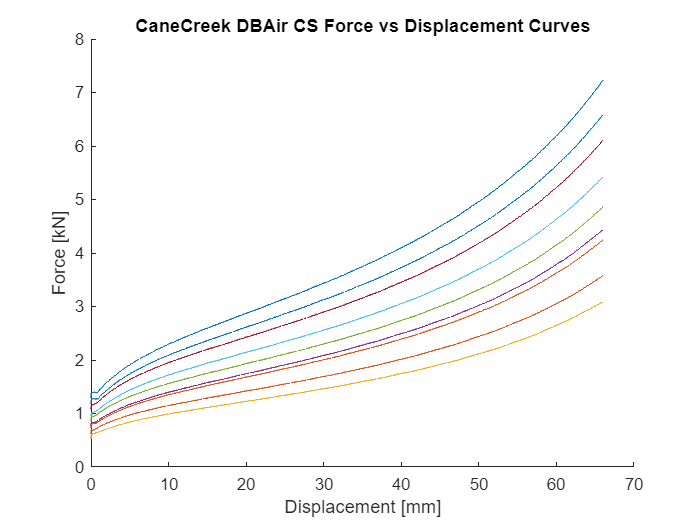

figure
hold on
for i = 1:length(procData(1,1,:))
    plot(procData(:,2,i),procData(:,3,i))
end
title("CaneCreek DBAir CS Force vs Displacement Curves")
xlabel("Displacement [mm]")
ylabel("Force [kN]")

for i = 1:length(pressures)
    procData(:,4,i) = smooth(gradient(procData(:,3,i)*1000)./gradient(procData(:,2,i)),500);
end

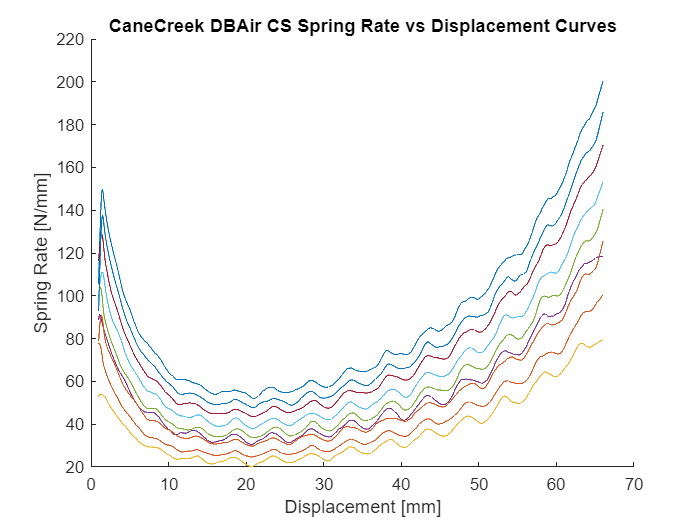

figure
hold on
for i = 1:length(procData(1,1,:))
    plot(procData(300:end,2,i),procData(300:end,4,i))
end
title("CaneCreek DBAir CS Spring Rate vs Displacement Curves")
xlabel("Displacement [mm]")
ylabel("Spring Rate [N/mm]")